# Simulink Fundamentals

This Live Script lesson introduces Simulink fundamentals. It is designed for complete beginners and includes low-code examples, guided model creation, and interactive tasks using Simulink tools.

Use Simulink Library Browser, block parameter dialog box, and the model window to explore the content.

## 1. What Is Simulink?

Simulink is a graphical modeling environment for dynamic systems. You build models from blocks, connect signals, set parameters, and then simulate the behavior of the system. Create a new blank model and open it in the Simulink Editor.

This is the final model we will be modeling today.

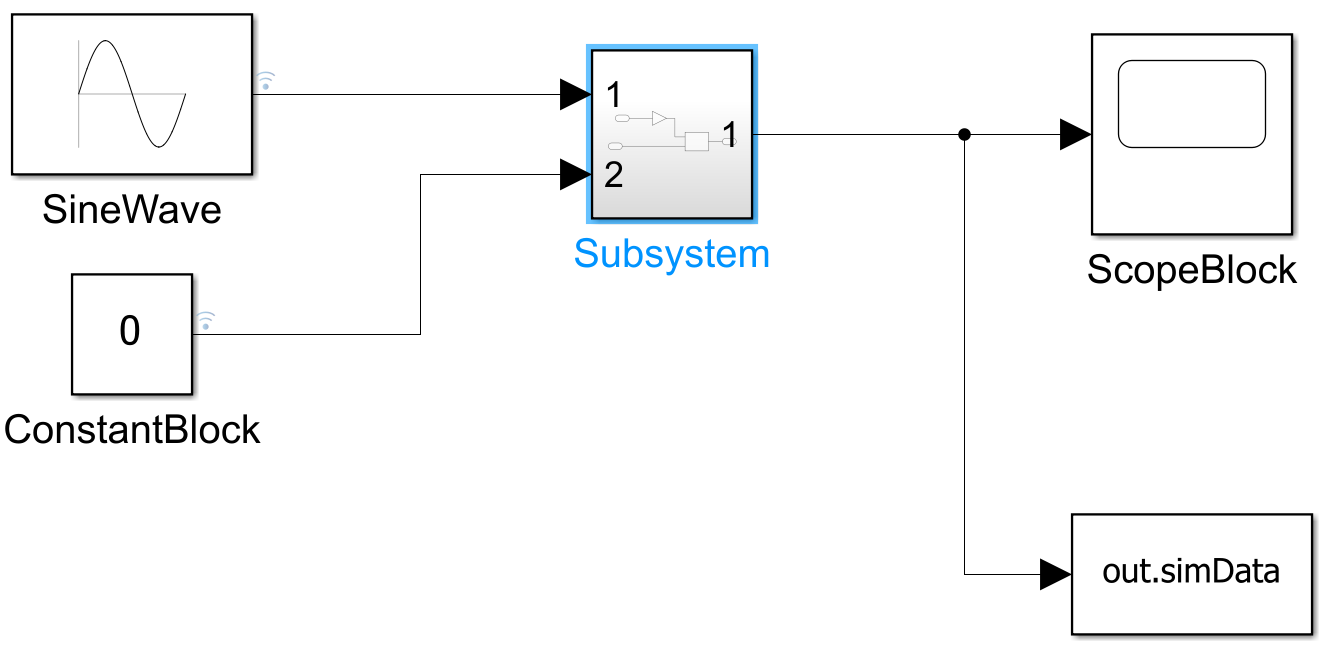

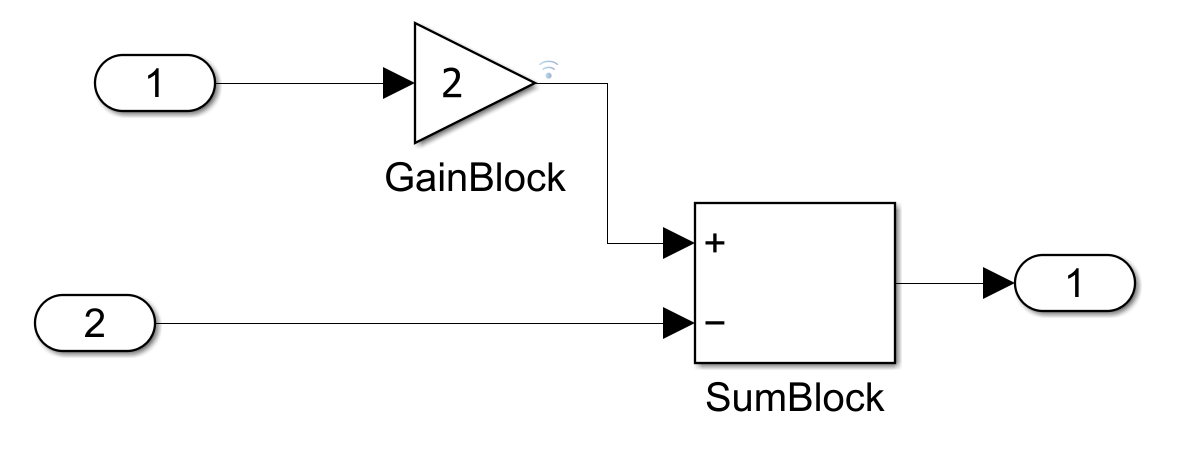

% Show the Simulink Library Browser from the Simulink tab in MATLAB.

## 2. Add Blocks to the Model.

Add a Sine Wave source, a Gain block, and a Scope block.

% Display the blocks that were added to the model.

## 3. Connect the Blocks.

Connect the output of the Sine Wave block to the Gain block, and then connect the Gain output to the Scope.

% Use the Simulink Editor to inspect the connection and move blocks.

## 4. Configure Block Parameters.

Use block dialog box or code to change the source frequency, gain value, and simulation stop time.

% Read parameters back to confirm.

## 5. Run the Simulation.

Simulate the model and view the signals in the Scope.

% In the Scope window, click the toolbar buttons to autoscale and zoom.
% Try changing the gain value to 1.5 or 5, then re-run this section.

## 6. Add a Constant Input and Sum Block.

Add a Constant block and Sum block to create a second signal path.

% Connect Sum output to Scope and To Workspace block.

## 7. Export Signal Data to the Workspace.

Use a To Workspace block to capture simulation output in MATLAB.

% Show the saved data structure.

## 8. Re-run the Simulation and Compare Results.

Run the simulation again after adding the constant input.

Add in MATLAB.

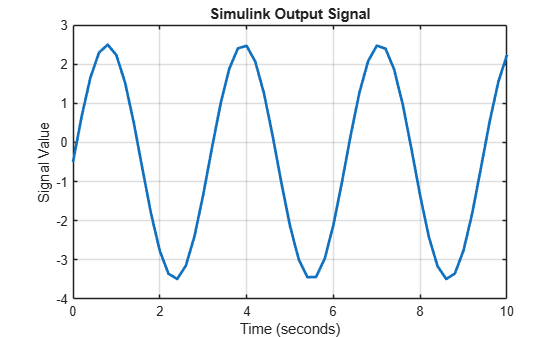

% Plot the signal in MATLAB for a second view.
figure;
plot(out.simData.time, out.simData.signals.values, "LineWidth", 2);
title("Simulink Output Signal")
xlabel("Time (seconds)")
ylabel("Signal Value")
grid on

## 9. Simulation Data Inspector (SDI).

A Scope block only shows signals that are physically wired to it. The Simulation Data Inspector (SDI) is a centralized tool that captures every logged signal from every simulation run, allowing you to browse and compare results without rewiring or re-running the model.

To log a signal for inspection:

- In your model, right-click on a signal line (the line connecting two blocks).

- Select Log Selected Signals from the context menu.

- A small antenna badge icon will appear on the signal line, indicating it is being logged.

To open the SDI and view logged data:

- Run your simulation.

- On the same SIMULATION tab, click the Data Inspector button.

- The SDI window opens. On the left-hand panel, you will see a list of all logged signals.

- Click the checkbox next to a signal name to plot it on the main graph.

To compare results from multiple runs:

- Change a parameter (e.g., the Gain value) and run the simulation again.

- In the SDI left panel, you will now see multiple Runs (e.g., Run 1, Run 2).

- Click the Compare tab at the top of the SDI window. The tool will overlay or subtract the signals, highlighting differences between the two runs.

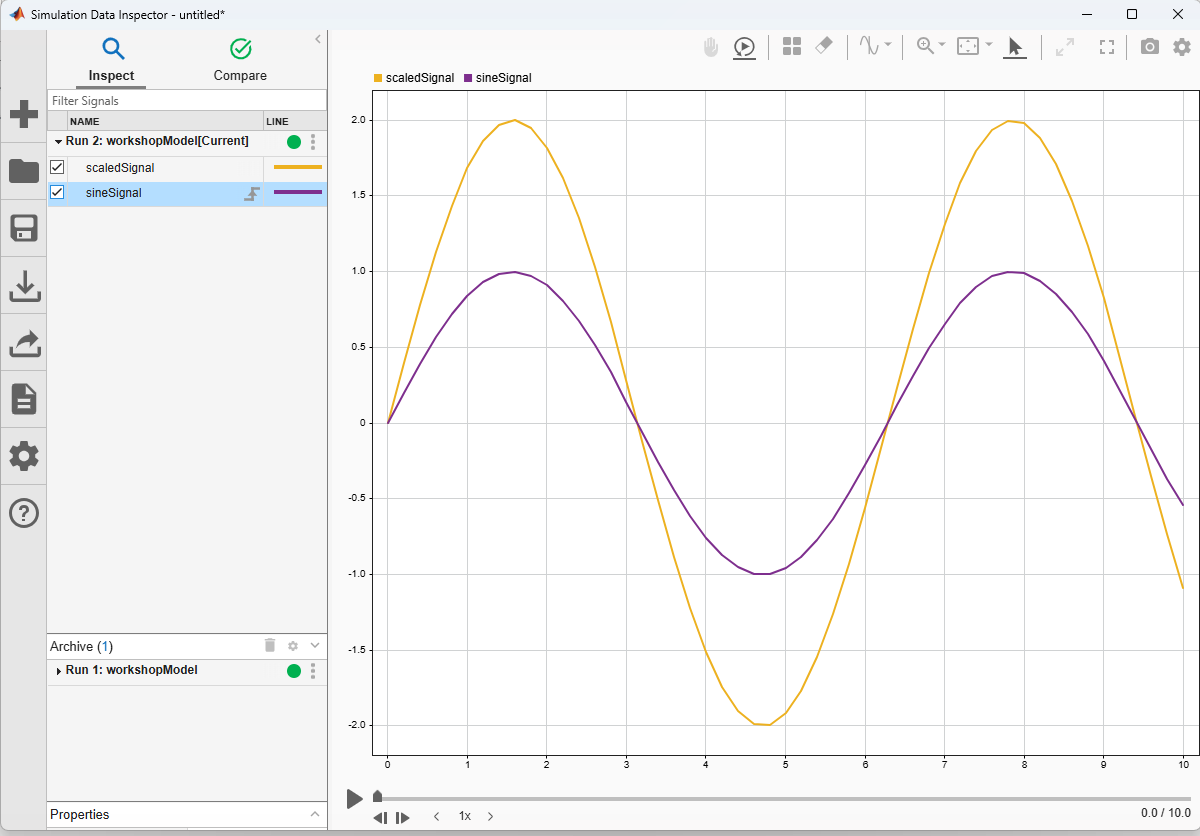

## 10. Subsystems.

Subsystems group a collection of blocks into a single reusable unit. This keeps large, complex models readable and organizes algorithms into logical stages. Think of a subsystem as a "container" that hides internal complexity while exposing only the necessary inputs and outputs.

To create a subsystem:

- In your model, click and drag to select multiple blocks (Gain Block & Sum Block).

- Right-click on the selected area and choose Create Subsystem from Selection.

- The selected blocks are replaced by a single Subsystem block. The internal connections are preserved.

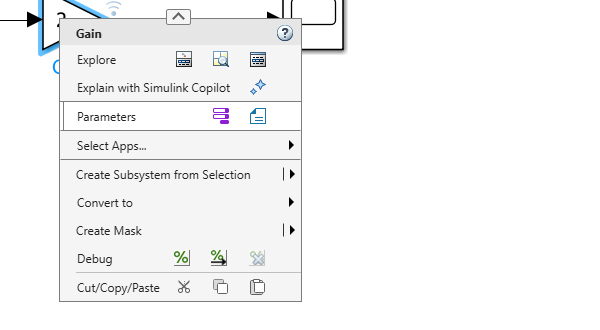

## 11. Function Block.

[MATLAB Function](https://www.mathworks.com/help/simulink/slref/matlabfunction.html) blocks enable you to define custom functions in Simulink models by using MATLAB code.

Delete your **Gain Block** in your subsystem and replaced it with a **MATLAB Function Block**. You can find the block in **Simulink**, **User-Defined Functions**.

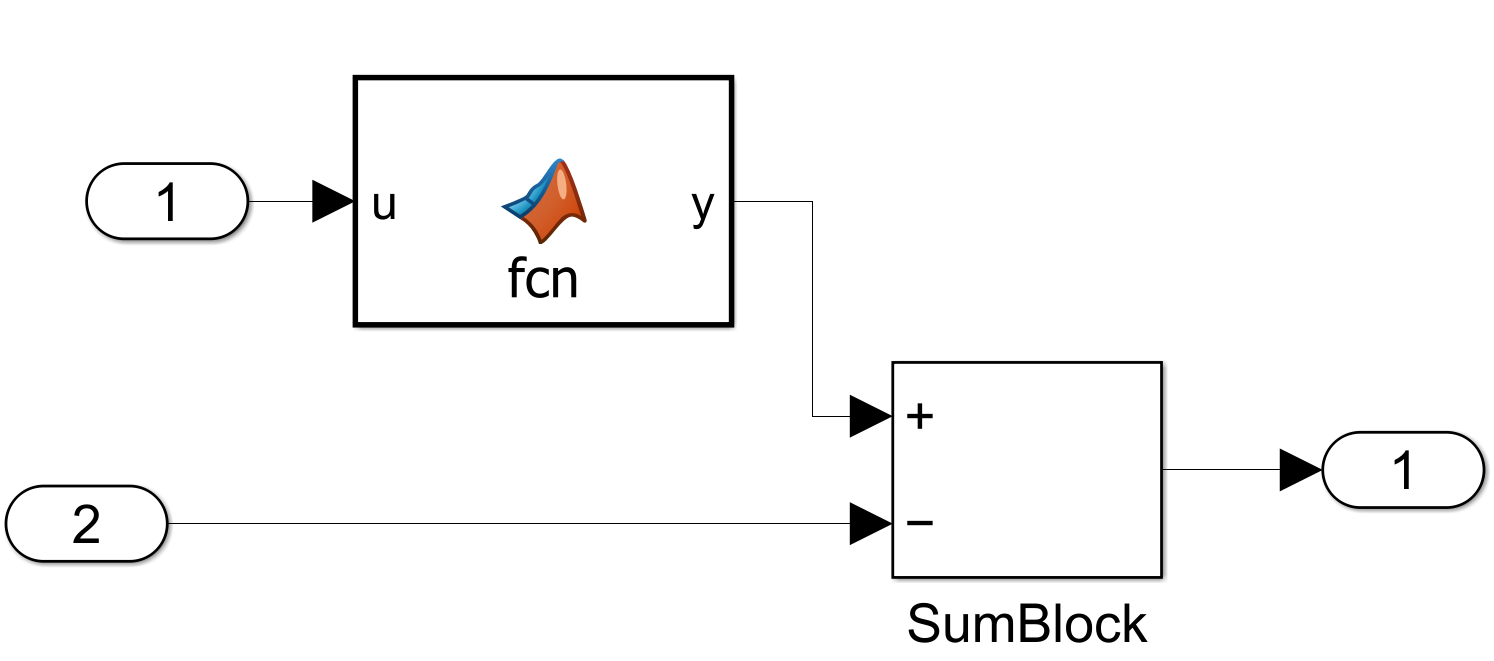

Open the **MATLAB Function Block** and write a code that represents the previous **Gain Block**.